# compute temporal summation ratio

## load data

whichDataSet  = 'preprocessed_data.mat';
whichDataType = 'fmri1'; % available data types : fmri1, fmri2, fmri1ecc

a  = load(fullfile(temporalRootPath, 'data', whichDataSet));
dt = double(a.dt.(whichDataType).data);
lb = a.dt.(whichDataType).nm;

% save parameters
svfname = 'df_results.mat';
svLoc   = fullfile(temporalRootPath, 'output');
b       = load(fullfile(svLoc, svfname));
rs      = b.rs;

## initiate

ind_rt = [];
rt     = [];

## analyze temporal summation ratio

switch whichDataType
    case 'fmri1' 
        mdt    = squeeze(mean(dt));
        ind_rt = computeRatio(mdt, 1 : 5);
        rt     = squeeze(median(ind_rt, 3));
    case 'fmri1ecc'
        for k = 1 : 2
            mdt       = squeeze(dt(k, :, :, :));
            ind_rt{k} = computeRatio(mdt, 1 : 5);
            rt{k}     = squeeze(median(ind_rt{k}, 3));
        end
    case {'fmri2'}
        mdt = squeeze(mean(dt));
        ind_rt{1} = computeRatio(mdt, 1:5);
        ind_rt{2} = computeRatio(mdt, 13:17);
        for k = 1 : 2
            rt{k} = squeeze(median(ind_rt{k}, 3));
        end
end

## Summarize data

if ~iscell(rt)
    mrt = median(rt, 2);
    srt = prctile(rt, [25, 75], 2);
else
    mrt = cellfun(@(x) median(x, 2), rt, 'UniformOutput', false);
    srt = cellfun(@(x) prctile(x, [25, 75], 2), rt, 'UniformOutput', false);
end

## save data


rs.(whichDataType).mTSR = mrt;
rs.(whichDataType).sTSR = srt;
save(fullfile(svLoc, svfname), 'rs')

## Visualize data

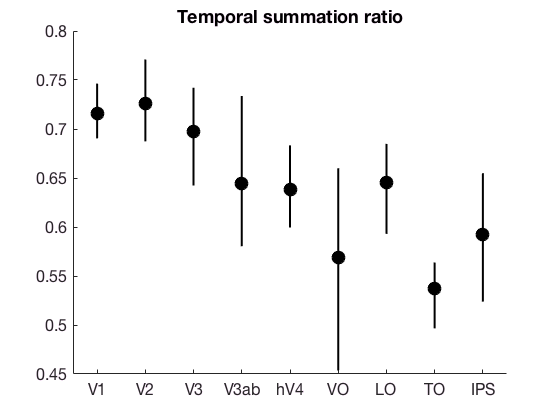


if ~iscell(rt)
    figure
    plot(mrt, 'ko', 'markerfacecolor', 'k'), hold on
    for k = 1 : length(mrt)
       plot([k, k], [srt(k, 1), srt(k, 2)], 'k-') 
    end
    set(gca, 'xtick', 1 : length(mrt), 'xticklabel', lb), xlim([0.5, length(mrt) + 0.5]), box off,
    title('Temporal summation ratio')
else
    for k0 = 1 : 2
        figure
        plot(mrt{k0}, 'ko', 'markerfacecolor', 'k'), hold on
        for k = 1 : length(mrt{k0})
            plot([k, k], [srt{k0}(k, 1), srt{k0}(k, 2)], 'k-')
        end
        set(gca, 'xtick', 1 : length(mrt{k0}), 'xticklabel', lb), xlim([0.5, length(mrt{k0}) + 0.5]), box off,
        title('Temporal summation ratio')
    end
end

function ind_rt = computeRatio(data, conds)
    
for icond = 1 : length(conds)
    ind_rt(:, :, icond) = data(:, :, conds(icond) + 1)./(data(:, :, conds(icond)).*2);
end
end